# MATLAB workshop

- Plotting data: points, errorbars

- Linear regression fit, plot, take parameters

- Importing data from files

- Parabolic fit

- Sine fit

- Custom expression fit

- Using functions for repetetive actions

clc; clear all; close all;

## Plotting 

### Plotting simple data

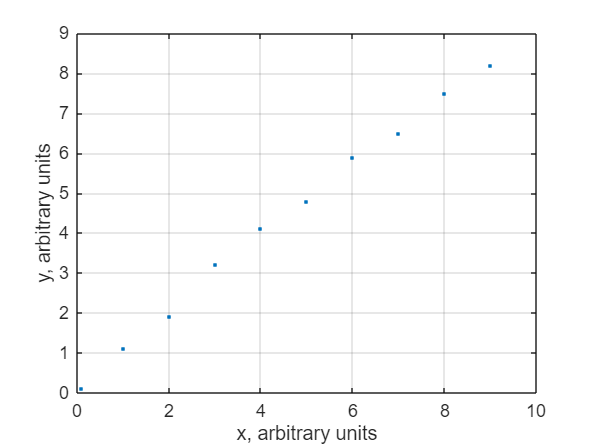

% synthetic data
x_ = [0.1 1   2   3   4   5   6   7   8   9]; 
y = [0.1 1.1 1.9 3.2 4.1 4.8 5.9 6.5 7.5 8.2]; 

figure
plot(x_, y, '.')
grid on
xlabel('x, arbitrary units')
ylabel('y, arbitrary units')

### Plotting data with errorbars

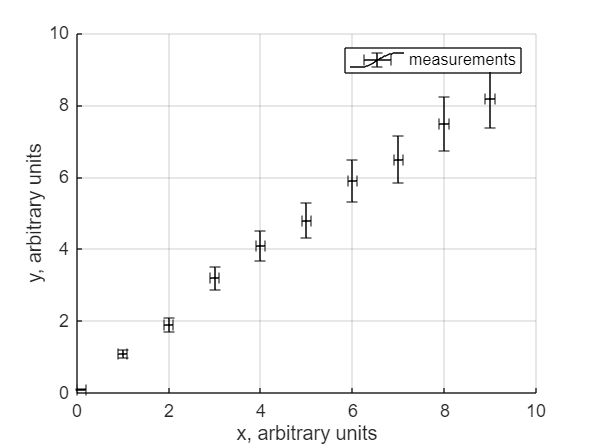

% uncertainties
y_err_relative = 0.1; %s 10 percent relative error
y_err = y .* y_err_relative; % absolute error
x_err = 0.10; % abs error for all values
figure
hold on
errorbar(x_, y, y_err, y_err, x_err, x_err, color='k')
hold off
legend('measurements')
grid on

xlabel('x, arbitrary units')
ylabel('y, arbitrary units')

## Linear regression fitting

see חוברת אנליזת נתונים ע'13

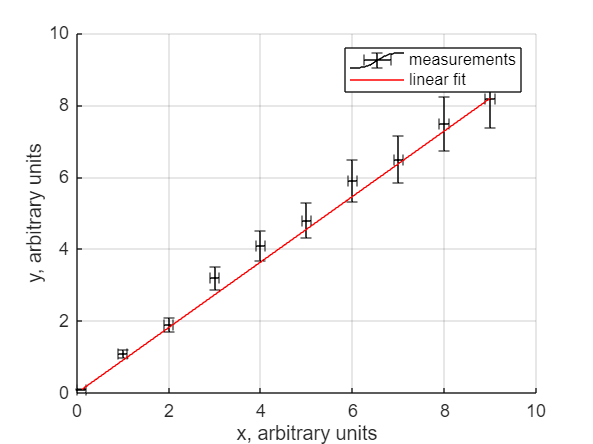

linear_regression = fitlm(x_,y);
R_squared = linear_regression.Rsquared.Ordinary;
b_coefficient = linear_regression.Coefficients.Estimate(1);
a_coefficient = linear_regression.Coefficients.Estimate(2);
b_error = linear_regression.Coefficients.SE(1);
a_error = linear_regression.Coefficients.SE(2);
figure
hold on
plot1 = errorbar(x_, y, y_err, y_err, x_err, x_err, color='k');
plot2 = plot(x_, x_ * a_coefficient,'r');

hold off
legend([plot1(1), plot2(1)], 'measurements', 'linear fit')
grid on
xlabel('x, arbitrary units')
ylabel('y, arbitrary units')

Linear regression line crosses most of error bars, therefore data with her uncertainties fits linear model.

#### Task: rebuild graph for realtive error of $y$ is 1%. Does the data fits linear model now?

## Importing data from file

Import and plot raw data

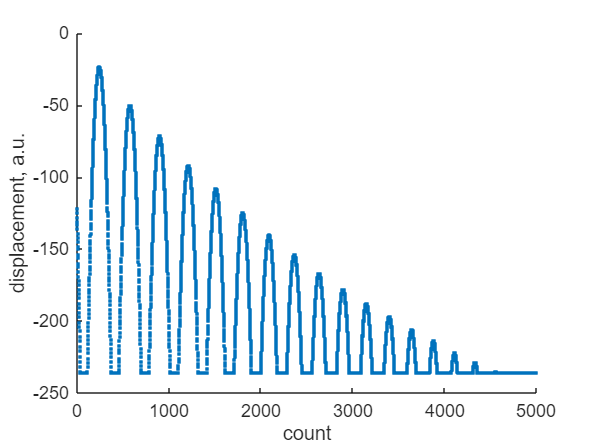

% import measurements to vector t
url = "https://raw.githubusercontent.com/tphlabs/data/refs/heads/main/Lab1_IV/d234.txt"; % place here path to your data
data = readmatrix(url);
ix = data(:,1); % ix in column 2
t = data(:,2); % time in column 2
x = data(:,4); % displacent in column 2
figure
hold on
plot(ix, x, '.')
ylabel('displacement, a.u.')
xlabel('count')

Cut part of data for further analysis

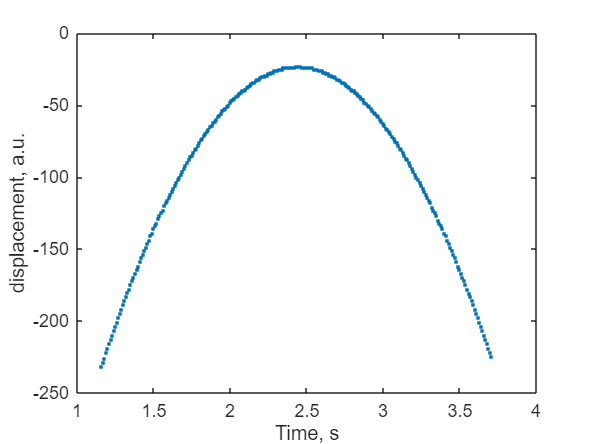

ix1 = 116;
ix2 = 371;
t_ = t(ix1:ix2);
x_ = x(ix1:ix2);



figure
plot(t_, x_, '.')
ylabel('displacement, a.u.')
xlabel('Time, s')

Plot velocity as digital derivative of displacement

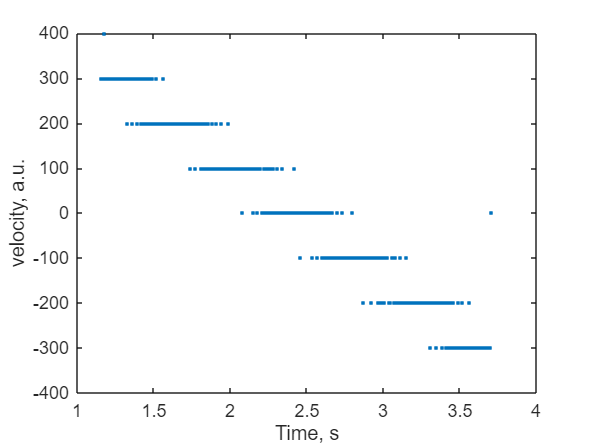

v_ = diff(x_) ./ diff(t_);
v_(end+1) = 0;

figure
plot(t_, v_, '.')
ylabel('velocity, a.u.')
xlabel('Time, s')

#### Task: Plot linear regression

Invalid use of operator.

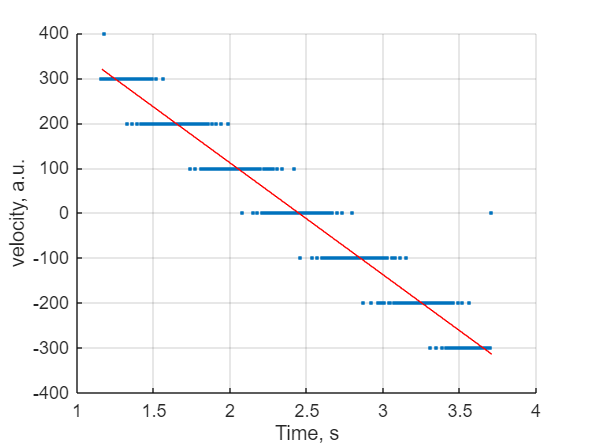

linear_regression = fitlm(t_,v_);
% your code here..